% Base paths and clearing
clear all
clc
addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/THINK/
addpath functions/ACT/

% Setup Pi
[robotPi, blinkLED]= SETUP_pi("192.168.16.68");

% Setup Servos
roverServos = I2C_Servo_pHAT(robotPi);
% Setup Sensors
[adcDevice1, adcDevice2] = SETUP_adc(robotPi);

% Setup PiCam
robotCam = cameraboard(robotPi,'Resolution','320x240');
SETUP_piCam(robotCam);  

% create index fro MDF table
WayPoint = (1:1:11);                                        
WayPoint = WayPoint';

% create inital target waypoints
xLongitude = [ 42.276295 ; 42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295;42.276295 ];
yLatitude = [ -71.227875 ; -71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875;-71.227875];

% build list of desired behaviors
% build Middion Definition File (MDF) table
Behavior = ['PauseDock______'; 'NavigationDock_'; 'FindDock_______'; 'Dock___________'; 
    'PauseNav_______'; 'NavPayload_____'; 'PayloadFindDock'; 'PayloadGoDock__'; 'PayloadDrop____';'PayloadFind____'; 'PayloadPickup__'];
MDF = table(WayPoint,xLongitude,yLatitude,Behavior)

MDF = 11×4 table
    WayPoint    xLongitude    yLatitude     Behavior  
    ________    __________    _________    ___________

        1         42.276       -71.228     [1×15 char]
        2         42.276       -71.228     [1×15 char]
        3         42.276       -71.228     [1×15 char]
        4         42.276       -71.228     [1×15 char]
        5         42.276       -71.228     [1×15 char]
        6         42.276       -71.228     [1×15 char]
        7         42.276       -71.228     [1×15 char]
        8         42.276       -71.228     [1×15 char]
        9         42.276       -71.228     [1×15 char]
       10         42.276       -71.228     [1×15 char]
       11         42.276       -71.228     [1×15 char]



WPn = 8;
piCamWindow = 1;
curvePlot = 1;
ACT_moveCam(roverServos,90,40);

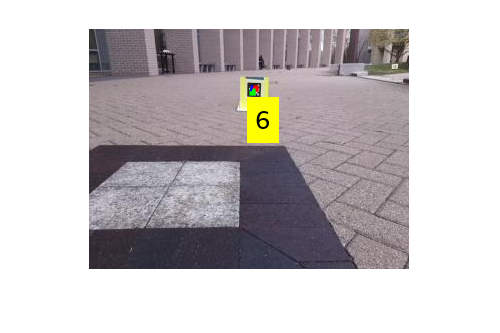

img = snapshotCustom(robotCam);
[a,b]= detectAprilTags(img,'dock');

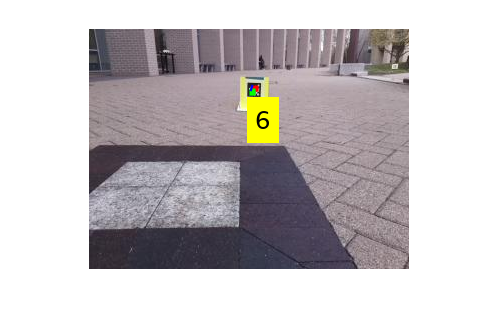

len = 6.9549

steerAngle = 1

ans = 1

THINK_go2PayloadDock(WPn, robotCam)

disp("A")

A


roverBehavior = 'PayloadGoDock__'

len = 6.9674

steerAngle = 1

roverBehavior = 'PayloadGoDock__'

len = 7.3924

steerAngle = -1

roverBehavior = 'PayloadGoDock__'

len = 8.3522

steerAngle = -2

roverBehavior = 'PayloadGoDock__'

len = 9.4516

steerAngle = -2

roverBehavior = 'PayloadGoDock__'

len = 10.7981

steerAngle = -3

roverBehavior = 'PayloadGoDock__'

len = 12.5355

steerAngle = -3

roverBehavior = 'PayloadGoDock__'

len = 14.6589

steerAngle = -3

roverBehavior = 'PayloadGoDock__'

len = 18.2989

steerAngle = -2

roverBehavior = 'PayloadGoDock__'

len = 23.9179

steerAngle = -3

roverBehavior = 'PayloadGoDock__'

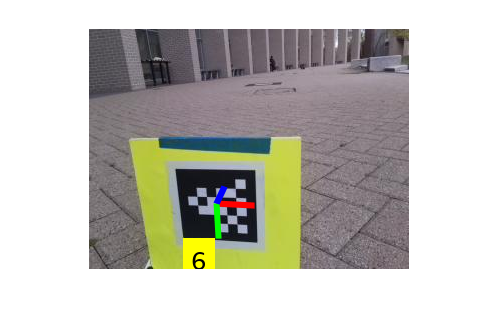

len = 35.2919

steerAngle = -29

roverBehavior = 'PayloadDrop____'

roverBehavior = 'PauseDock______'

Error using THINK_pause
Too many output arguments.

Error in THINK (line 11)
           [steerAngle, velocity, WPn] = THINK_pause(WPn, roverServos, roverCam);

while 1
    ACT_moveRover(roverServos,0,0);
    roverBehavior = MDF{WPn,4}
    [steerAngle,velocity, WPn] = THINK(WPn, roverBehavior, robotCam, roverServos, adcDevice1, adcDevice2, piCamWindow, curvePlot);
    ACT_moveRover(roverServos,steerAngle,velocity);
    pause(0.5)
end